# **Session 5: Design of controllers in the frequency domain**

The practices of the Automatic Control subject consist in the study of a servomechanism of angular positioning (LJ Technical Systems) controlled by a PC. The laboratory sessions P1 and P2 focus on the experimental analysis of the temporal and frequency responses of the system, respectively. Sessions P3 and P4 are dedicated to the design of PID controllers. Finally, in session P5 controllers will be designed in the frequency domain.

**OBJECTIVE: Design a controller in the frequency domain for the position output of the plant studied in previous sessions so that the closed-loop system meets certain specifications in the frequency domain.**

**In this session the student has to:**

- **Design a controller by phase advance.**

- **Experimentally verify the designed control system.**

% Alternate between the experiment data and the directory Results
% If you want to use the data in the directory Results = false
% If you want to use your own data = true
useExperimentalData = false;

# Introduction

In this practice, the phase advance and delay controllers are presented. These controllers are set to be in series (cascade) with the plant to be controlled and aim to modify the behavior of the system in closed loop. The control system must satisfy certain specifications defined in the frequency domain by means of a gain margin and/or a phase margin. For the design of controllers in the frequency domain, the discrete time systems are transformed into similar systems of continuous time and are then is antitransformed to have a digital controller. The methodology for the design of advance or phase delay controllers for continuous time systems is detailed below; then four exercises are proposed.

The generic transfer function in s of an advance or phase delay controller is given by


$$G_c \left(s\right)=K\frac{\frac{s}{\omega_z }+1}{\frac{s}{\omega_p }+1}$$


The relation $\alpha =\frac{\omega_p }{\omega_z }$ for the case of $\omega_p >\omega_z$, or $\alpha =\frac{\omega_z }{\omega_p }$ for the case of $\omega_p <\omega_z$ it's called controller length.

**PHASE ADVANCE CONTROLLERS**

They correspond to the case in which $\omega_z <\omega_p$ and they serve to improve the transient response. In a certain range of frequencies, they increase (*advance*) the phase of the controlled system. The following procedure allows to determine how much the phase will increase and on what frequency the controller action should focus.

The equations that must be verified so that $\Phi_{\mathrm{md}}$ be the phase margin of the feedback system are:


$$\begin{array}{l}
|G_c \left(j\;\omega_c \right)||\mathrm{GH}\left(j\;\omega_c \right)|=1\\
180+\mathrm{arg}\left(G_c \left(j\;\omega_c \right)\right)+\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_c \right)\right)=\gamma_d 
\end{array}$$


Taking $\omega_c =\sqrt{\omega_z \omega_p }=\omega_z \sqrt{\alpha }$ can be written as


$$\begin{array}{l}
|G_c \left(j\;\omega_z \sqrt{\alpha }\right)||\mathrm{GH}\left(j\;\omega_z \sqrt{\alpha }\right)|=1\\
180+\mathrm{arg}\left(\frac{\alpha -1}{2\sqrt{\alpha }}\right)+\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_z \sqrt{\alpha }\right)\right)=\Phi_{\mathrm{md}} 
\end{array}$$


The design of the controller is done by looking for an approximate solution of the previous system of equations and finally verifying that the closed loop system satisfies the specifications. It is a method of solution by trial and error. The approximate solution is obtained by solving:


$$\begin{array}{l}
\theta_c =\Phi_{\mathrm{md}} +\Delta -\Phi_{\mathrm{GH}} \\
\alpha =\frac{1+\mathrm{sin}\;\theta_c }{1-\mathrm{sin}\;\theta_c }\\
|\mathrm{GH}\left(j\;\omega_c \right)|=\frac{1}{\sqrt{\alpha }}
\end{array}$$


where $\Phi_{\mathrm{GH}}$ is the phase margin of the open-loop system multiplied by the stationary gain of the controller and $\Delta$ it is an additional margin of security that it introduces since an approximate system of equations is solved and no part of the system is exact. The solution provides the maximum phase advance provided by the controller, $\theta_c$, the length of the controller $\alpha$ and the central frequency $\omega_c$.

The pulsations $\omega_z$ and $\omega_p$ are obtained from $\alpha$ and $\omega_c$.


$$\omega_z =\frac{\omega_c }{\sqrt{\alpha }},\;\;\;\;\;\omega_p =\omega_c \sqrt{\alpha }=\omega_z \alpha$$


COMMENTS:

In case of obtaining $\theta_c >60$ is taken $k$ so that $\frac{\theta_c }{k}<60$, the controller is designed with $\frac{\theta_c }{k}$ and it applies


$$G_c ={\left(\frac{\frac{s}{\omega_z }+1}{\frac{s}{\omega_p }+1}\right)}^k$$


Previously, the above equation should be rewritten as


$$|\mathrm{GH}\left(j\;\omega_c \right)|=\frac{1}{{\left(\sqrt{\alpha }\right)}^k }$$


**PHASE DELAY CONTROLLERS**

In this case $\omega_p <\omega_z$ and serve to improve the accuracy in steady state. The qualifier of phase delay comes from the fact that, in a certain frequency interval, the controller reduces (*delays*) the phase of the controlled system. As in the previous case, the equations that the controlled system must satisfy are:


$$\begin{array}{l}
|G_c \left(j\;\omega_c \right)||\mathrm{GH}\left(j\;\omega_c \right)|=1\\
180+\mathrm{arg}\left(G_c \left(j\;\omega_c \right)\right)+\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_c \right)\right)=\gamma_d 
\end{array}$$


In this case the frequency is determined $\omega_c$ that would provide the desired phase margin of the control system and is calculated $\alpha$ so that $\omega_c$ be the cutoff frequency to 0dB of this system. The controller is centered enough to the left of $\omega_c$ so that its effect is negligible in the phase of $|G_c \mathrm{GH}\left(j\;\omega_c \right)|$. As in the case of controllers by phase advance, the procedure is not exact but approximate, which is why you have to introduce an additional margin of security and do a check at the end.

The variables $\theta_c ,\omega_c$ and $\alpha$ are obtained by solving the equations:


$$\begin{array}{l}
\theta_c =\gamma_d +\Delta -180\\
\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_c \right)\right)=\theta_c \\
\alpha =|\mathrm{GH}\left(j\;\omega_c \right)|
\end{array}$$


Finally,


$$\omega_z =\frac{\omega_c }{10},\;\;\omega_p =\frac{\omega_z }{\alpha }$$


COMMENTS:

- The algorithm can only be applied if the equation $\arg \left(\textrm{GH}\left(j\;\omega_c \right)\right)=\theta_c$ has a solution.

- In the case that $\alpha >12$ is designed with $\alpha^{\wedge } =\sqrt[k]{\alpha }$ for $k$ natural sufficiently large and is applied


$$G_c ={\left(\frac{\frac{s}{\omega_z }+1}{\frac{s}{\omega_p }+1}\right)}^k$$


# Exercise 16: Determination of the system's gain and phase margins.

Consider the laboratory plant with position output. Using MATLAB, check that the gain and phase margins of the digital system and the equivalent system that results from applying the bilinear transformation match.

% Parameters of the plant 
Kpot=1.62;
N=9;
K0=0.82/0.017;
tau0=0.26;
planta=tf([Kpot*K0/N],[tau0,1,0])


planta =
 
     8.682
  ------------
  0.26 s^2 + s
 
Continuous-time transfer function.



% Discrete time model
Ts=0.01;
plantad=c2d(planta,Ts,'zoh') ;

% Bilinear transform
plantaw=d2c(plantad,'tustin') ;

% Verification of the coincidence in the calculation of margins
display('Margins of the bilineal plant')

Margins of the bilineal plant


[Gmw,Pmw,Wcgw,Wcpw]=margin(plantaw)

Gmw = 23.1838

Pmw = 35.1259

Wcgw = 27.8243

Wcpw = 5.1783

display('Margins of the discrete plant')

Margins of the discrete plant


[Gmd,Pmd,Wcgd,Wcpd]=margin(plantad)

Gmd = 23.1858

Pmd = 35.1258

Wcgd = 27.6481

Wcpd = 5.1772

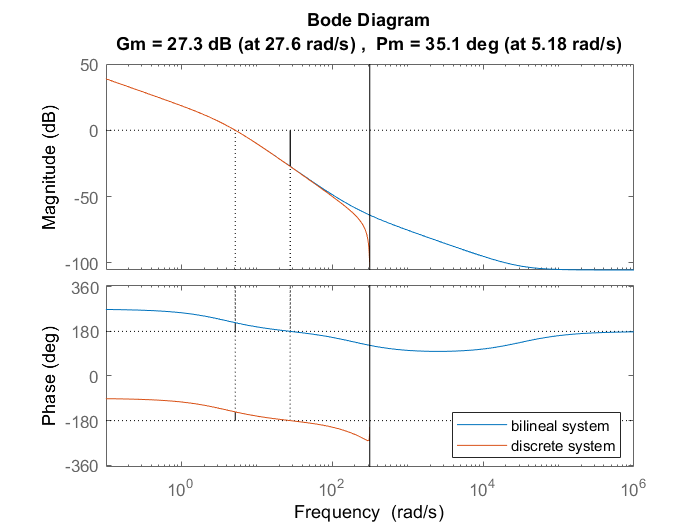

margin(plantaw)
hold on
margin(plantad)
legend('bilineal system','discrete system','Location', 'SouthEast')

As it can be seen, the margins obtained by the *margin()* command of the two systems to be analyzed are exactly the same

# Exercise 17: Design of a phase advance controller.

With the help of MATLAB, design a phase advance controller that makes the closed loop system, for the position control of the 

laboratory plant, with a sampling period Ts = 0.01, have a phase margin of 45º and a static error of the 10% in front of a ramp input. Consider an additional safety phase margin of $\Delta =15º$.

% Parameters of the plant
Kpot=1.62;
N=9;
K0=0.82/0.017;
tau0=0.26;
planta=tf([Kpot*K0/N],[tau0,1,0])


planta =
 
     8.682
  ------------
  0.26 s^2 + s
 
Continuous-time transfer function.



% Discrete time model
Ts=0.01;
plantad=c2d(planta,Ts,'zoh') ;

% Bilinear transform
plantaw=d2c(plantad,'tustin') ;

% Calculation of the necessary gain
% Velocity error coefficient
errordes=0.1;
Kv=(1/errordes);

% Calculation of the gain increase needed
% (Controller gain)
Kvplanta=Kpot*K0/N;
Kcontrolador=Kv/Kvplanta

Kcontrolador = 1.1518

% Calculation of the phase margin
[Gm,Pm,Wcg,Wcp]=margin(Kcontrolador*plantaw)

Gm = 20.1290

Pm = 32.6959

Wcg = 27.8243

Wcp = 5.6375

% Calculation of the phase that the controller must add
gamma=45;
delta=15;
theta=(gamma+delta-Pm)* pi /180;

% Calculation of the alpha parameter
alpha=(1+sin(theta))/(1-sin(theta));

% Search for the point where the system has the gain 1/sqrt(alpha)
[aux1,aux2,aux3,wc]=margin(Kcontrolador*plantaw*sqrt(alpha));
wc

wc = 7.4975

% Pole and zero placement
wz=wc/sqrt(alpha); %Avance
wp=wz*alpha ;

% Construction of the controller
Gcw=tf([1/wz,1],[1/wp,1]);

% Reverse Bilinear: obtaining the Controller
Gcz=c2d(Gcw,Ts,'tustin')


Gcz =
 
  2.597 z - 2.481
  ---------------
    z - 0.8841
 
Sample time: 0.01 seconds
Discrete-time transfer function.



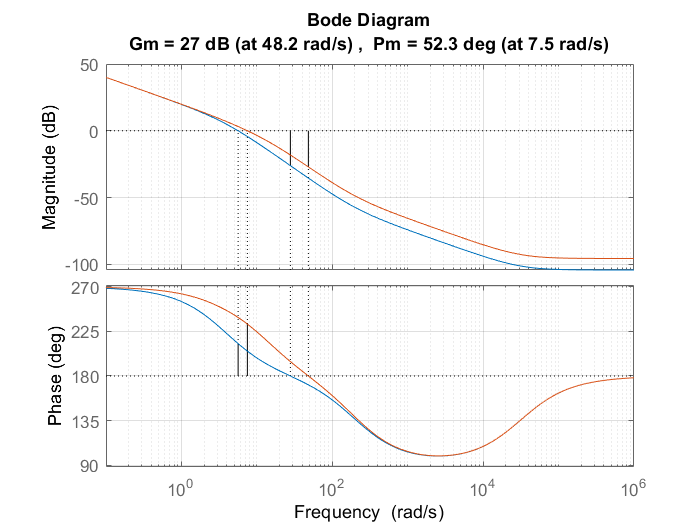

% Frequency response in open-loop
% (Verifying the fulfillment of the specifications)
figure
Gczplantad=series(Kcontrolador*Gcz,plantad);
Gczplantaw=d2c(Gczplantad,'tustin');
margin(Kcontrolador*plantaw)
hold on


margin(Gczplantaw)
grid

disp('see if you like the new phase margin ; press any key')

see if you like the new phase margin ; press any key


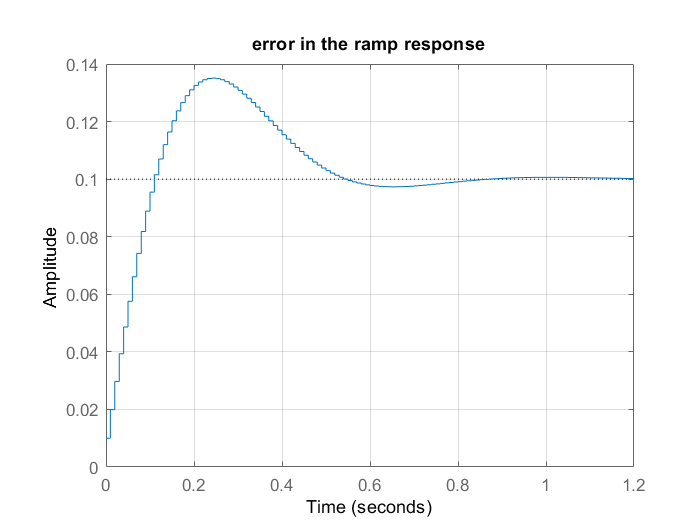

pause

% Construction of the closed-loop system
closed=feedback(Gczplantad,1);
err=1-closed;

% Verification of the temporary response
figure
grao=tf([1 0],[1,-1],Ts);
step(minreal(err*grao)*Ts) ;
grid
title('error in the ramp response')

% Preparation of data for Simulink 

disp('coefficients of the transfer function of the unit gain controller in z')

coefficients of the transfer function of the unit gain controller in z


Kc=dcgain(Gcz)

Kc = 1

Zc=zero(Gcz)

Zc = 0.9553

Pc=pole(Gcz)

Pc = 0.8841

# Exercise 18: Simulation analysis.

- Compare the bode diagrams of the open-loop system with the designed controller by adding delays of one, two, three, ... sampling periods. 

- How many periods of delay can the system sustain while maintaining stability?

Execute the model P5_Ex19.slx, define the parameters of the designed controller. See the temporary response of the system.

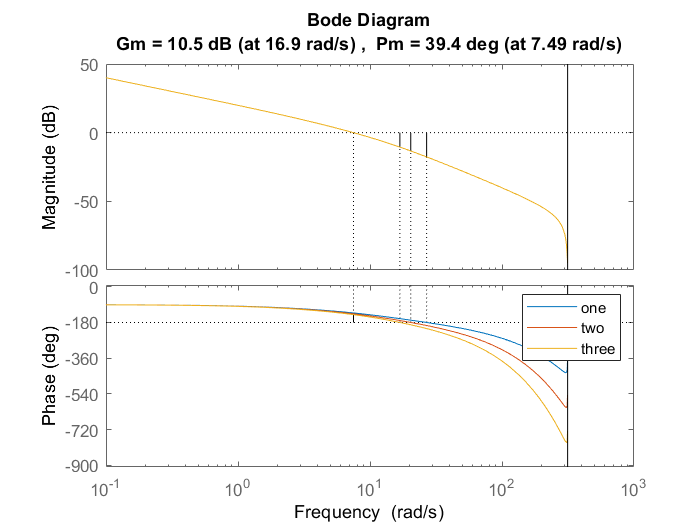

% Delays generation
unret=tf([1],[1 0],Ts) ;
dosret=tf([1],[1 0 0],Ts) ;
tresret=tf([1],[1 0 0 0],Ts) ;

% Visualization of the different Bode diagrams
figure
margin(unret*Gcz*plantad*Kcontrolador)
hold all
margin(dosret*Gcz*plantad*Kcontrolador)
margin(tresret*Gcz*plantad*Kcontrolador)
legend('one','two','three')

On one hand, by creating more delays, we can observe how the system becomes unstable from delays of 13 sampling periods. On the other hand, simulating the model P5_Ex19.slx we can see how in the response to a ramp type input we get an error of 0.01.

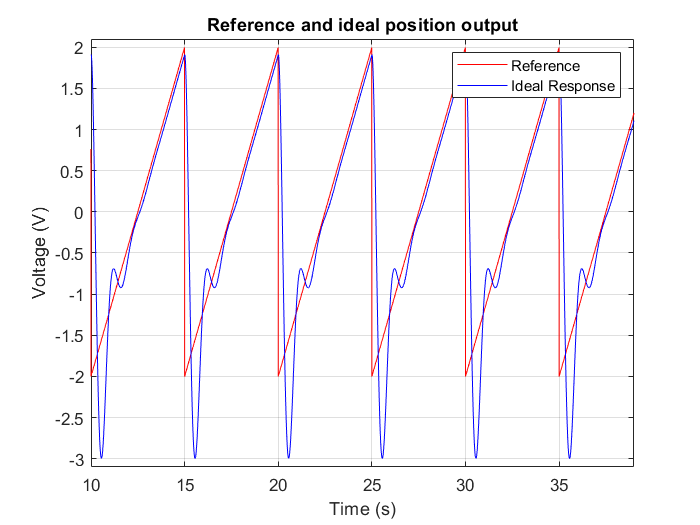

if useExperimentalData
    % Use Simulink
    open P5_Ex19.slx
    run P5_Ex19.slx;
else
    FileName   = 'P5_real_ideal.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac5'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,2,:)],'r')
hold on; grid on;
plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,3,:)],'b')
xlim([10 39]); ylim([-3.1 2.1]);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Reference and ideal position output');
legend('Reference','Ideal Response');

# Exercise 19: Implementation of the phase advance controller.

Execute model P5_Ex20.slx and visualize the behavior of the experimental control system and check the specification relative to the velocity constant.

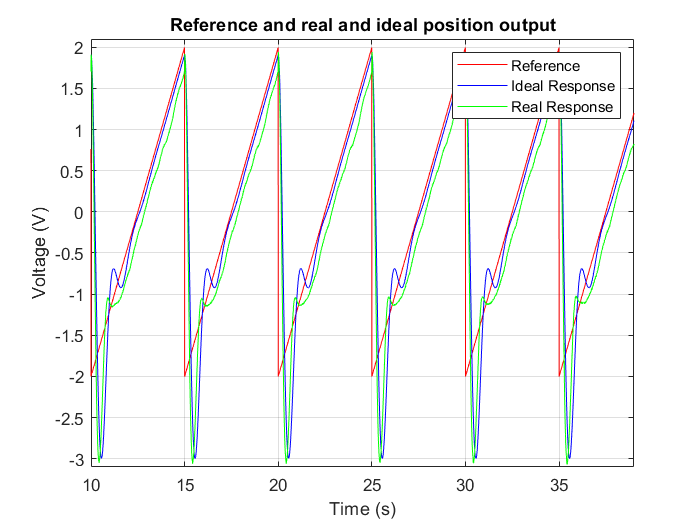

if useExperimentalData
    % Use Simulink
    open P5_Ex19.slx
    run P5_Ex19.slx;
else
    figure
    plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,2,:)],'r')
    hold on; grid on;
    plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,3,:)],'b')
    plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,1,:)],'g')
    xlim([10 39]); ylim([-3.1 2.1]);
    xlabel('Time (s)');
    ylabel('Voltage (V)');
    title('Reference and real and ideal position output');
    legend('Reference','Ideal Response','Real Response'); 
end

As it can be seen, the real output has a constant error in front of a ramp-type input, but the real response is not the same as the ideal, this difference comes from the unmodelled dynamics of the system.